# **Noise **

% Params
noise_power=100e-6; % 100 uW
bandwidth=1e6; % 1 MHz
fs=2*bandwidth; % Nyquist
duration=0.1; % Signal duration
j=sqrt(-1); % im unit

% PSD
noise_density = noise_power / bandwidth; % Watt/Hz

% Generate complex AWGN
num_samples = fs * duration;
noise_signal = sqrt(noise_density) * (randn(num_samples,1)+j*randn(num_samples,1));

[pxx, f] = pwelch(noise_signal, [], [], [], fs/2, 'centered');

% Convert PSD to dBm/Hz
psd_noise_dBm_Hz = 10 * log10(pxx)+30;

# **Signal**

% Parameters for sinusoidal signal
signal_power_dBm = 0 % dBm

signal_power_dBm = 0

signal_power = 10^((signal_power_dBm-30)/10); % Watt

signal_freq = 200e3 % 200 kHz

signal_freq = 200000


% Generate sinusoidal signal
t = (0:num_samples-1)' / fs; % Time vector
amplitude = signal_power/sqrt(2); % Convert power to amplitude
sin_signal = amplitude * cos(2*pi*signal_freq*t); % Real Signal
complex_signal = amplitude*exp(j*2*pi*signal_freq*t)

complex_signal = 1.0e-03 *

   0.7071 + 0.0000i
   0.5721 + 0.4156i
   0.2185 + 0.6725i
  -0.2185 + 0.6725i
  -0.5721 + 0.4156i
  -0.7071 + 0.0000i
  -0.5721 - 0.4156i
  -0.2185 - 0.6725i
   0.2185 - 0.6725i
   0.5721 - 0.4156i



% Estimate PSD of sin and complex signal using Welch's method
[pxx_sin, freq_sin] = pwelch(sin_signal, [], [], [], fs/2, 'centered');
[pxx_complex, freq_comp] = pwelch(complex_signal, [], [], [], fs/2, 'centered');

psd_sin_dBm_Hz = 10 * log10(pxx_sin) + 30;
psd_complex_dBm_Hz = 10 * log10(pxx_complex) + 30;

# **Plot**

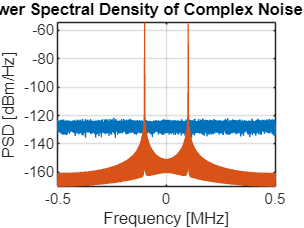

% Plot the PSD's
figure;
plot(f / 1e6, psd_noise_dBm_Hz);
hold on;
%plot(freq_comp, psd_complex_dBm_Hz);
plot(freq_sin/1e6, psd_sin_dBm_Hz);
title('Power Spectral Density of Complex Noise Signal');
xlabel('Frequency [MHz]');
ylabel('PSD [dBm/Hz]');
grid on;